# **CONTINUM > Example 03-A**

**Example: Reducing the index**

Consider a continuous stirred tank reactor (CSTR) in which occurs the reaction $A\rightleftharpoons B \rightarrow C$, leading to the following set of equations:

## 
$$\begin{array}{l}
\frac{{\textrm{dx}}_1 }{\textrm{dt}}=1-{\mathrm{x}}_1 -{\mathrm{x}}_4 \\
\frac{{\textrm{dx}}_2 }{\textrm{dt}}={-\mathrm{x}}_2 \left(1+{\mathrm{D}}_{\mathrm{a}} {\mathrm{e}}^{-\mathrm{g}/{\mathrm{x}}_3 } \right)+{\mathrm{x}}_4 \\
\frac{{\textrm{dx}}_3 }{\textrm{dt}}=1-{\mathrm{x}}_3 -\beta \;\left({\mathrm{x}}_3 -\mathrm{c}\right)+{\mathrm{H}}_1 {\mathrm{x}}_4 +{\mathrm{H}}_2 {\mathrm{x}}_2 {\mathrm{D}}_{\mathrm{a}} {\mathrm{e}}^{-\mathrm{g}/{\mathrm{x}}_3 } \\
0={\mathrm{K}}_{\textrm{eq}} -{\mathrm{x}}_4 \left(1+{\mathrm{K}}_{\mathrm{eq}} \right)+{\mathrm{x}}_2 {\mathrm{D}}_{\mathrm{a}} {\mathrm{e}}^{-\mathrm{g}/{\mathrm{x}}_3 } 
\end{array}$$


First, we need to create a file in which those equations are implemented:

This file was saved as **cstr_rev_idx1.m***. *Now, we are able to use the CONTINUUM package.

## **1) Create the Variables**

% Syntax: var = Variable(tag, var0);
%         tag is the display name (all tags must be unique).
%         var0 is used as initial guess (steady state solution) or initial condition (dynamic solution).
clc
clear
x1 = Variable('x_1', 0);
x2 = Variable('x_2', 0);
x3 = Variable('x_3', 1);
x4 = Variable('x_4', 1);
% x5 = Variable('x_5', -5/4);

## 2) Create the Parameters

% Syntax: par = Parameter(tag, par0, lb, ub, fixed); 
%         tag is the display name (all tags must be unique).
%         par0 is used as initial guess.
%         lb is the parameter lower bound.
%         ub is the parameter upper bound.
%         fixed is a boolean: false (default), when the parameter is used in search; true, when it is fixed.
Da   = Parameter('D_a', 9.5, 0, 10); 
g    = Parameter('g', 30, 0, 100); 
beta = Parameter('\beta', 3, 0, 10); 
c    = Parameter('c', 5, 0.5, 10); 
H1   = Parameter('H_1', 10, 0, 15); 
H2   = Parameter('H_2', 65, 0, 100); 
Keq  = Parameter('K_{eq}', 55, 0, 100); 

## 3) Create the mass matrix (for index $\ge 1$) and the individual index vector (for index $\ge 2$) 

MassMatrix = [ 1,0,0,0
               0,1,0,0
               0,0,1,0
               0,0,0,0 ];
           
vIndex = [1, 1, 2, 2];

## 4) Create the problem

P = Continum(@cstr_rev_idx1, [x1, x2, x3, x4], [Da, g, beta, c, H1, H2, Keq], MassMatrix, vIndex); 
% Variables and parameters's positions must be consistent with the defined in 'cstr_rev_idx1.m' file

% Show initial model analysis
P.ShowReport;



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_rev_idx1.m
    Variables ....................................... x1 = 0, x2 = 0, x3 = 1, x4 = 1
    Search Parameters ............................... Da = 9.500000e+00, g = 30, beta = 3, c = 5, H1 = 10, H2 = 65, Keq = 55

* Model Analysis

    Differential Index .............................. 1
    Explicit Algebraic Eqs .......................... 1
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 3


================= End of Report =================



## 5) Simulation tests

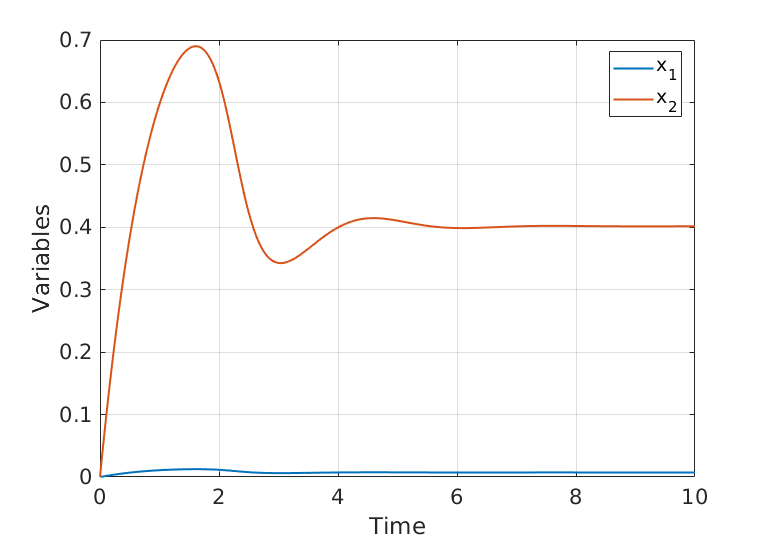

% Setup the integrator:
P.dynopt.abstol = 1e-10;
P.dynopt.reltol = 1e-08;
P.dynopt.solver = 'dasslc';

% Simulate
P.Simulate([0,10]);

% Plot time series
P.PlotTimeSeries([x1,x2]);

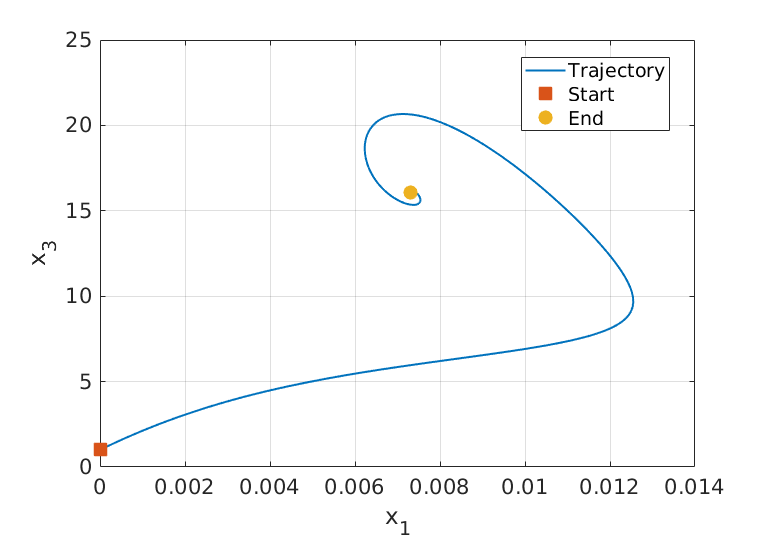

% Plot phase plane
P.PlotPhasePlane(x1,x3)

## 6) Search for Hopf bifurcation point

% Get to same results as idx2 case. 
P.SetValue([Da, g, beta, c, H1, H2, Keq],[9.454423, 32.5556, 3.1651, 4.516629, 9.581102, 65.32514, 55.61635]);


	 Class: Parameter
	 Tag:   D_a
	 Value: 9.4544e+00
	 Lower: 0.0000e+00
	 Upper: 1.0000e+01
	 Fixed: no

	 Class: Parameter
	 Tag:   g
	 Value: 3.2556e+01
	 Lower: 0.0000e+00
	 Upper: 1.0000e+02
	 Fixed: no

	 Class: Parameter
	 Tag:   \beta
	 Value: 3.1651e+00
	 Lower: 0.0000e+00
	 Upper: 1.0000e+01
	 Fixed: no

	 Class: Parameter
	 Tag:   c
	 Value: 4.5166e+00
	 Lower: 5.0000e-01
	 Upper: 1.0000e+01
	 Fixed: no

	 Class: Parameter
	 Tag:   H_1
	 Value: 9.5811e+00
	 Lower: 0.0000e+00
	 Upper: 1.5000e+01
	 Fixed: no

	 Class: Parameter
	 Tag:   H_2
	 Value: 6.5325e+01
	 Lower: 0.0000e+00
	 Upper: 1.0000e+02
	 Fixed: no

	 Class: Parameter
	 Tag:   K_{eq}
	 Value: 5.5616e+01
	 Lower: 0.0000e+00
	 Upper: 1.0000e+02
	 Fixed: no



% Setup optimizer:
P.optopt.algorithm = 'simplex'; % {'simplex','hybrid','swarm','levenberg-marquardt'}
P.optopt.display = 'iter'; % {'none','iter'}
P.optopt.objectiveform = 'absolute'; % {'absolute', 'quadratic'}
P.optopt.tolfun = 1e-10;
P.optopt.tolx = 1e-10;

% HopfSearch
P.HopfSearch;

 
 Iteration   Func-count     min f(x)         Procedure
     0            1      6.56158e-05         
     1            8      6.56158e-05         initial simplex
     2           10      6.56158e-05         contract outside
     3           12      6.56158e-05         contract outside
     4           13      6.56158e-05         reflect
     5           15      6.56158e-05         contract inside
     6           16      6.56158e-05         reflect
     7           17      6.56158e-05         reflect
     8           19      6.56158e-05         contract inside
     9           21      6.56158e-05         contract inside
    10           23      6.56158e-05         contract inside
    11           25      6.56158e-05         contract inside
    12           27      6.56158e-05         contract inside
    13           28      6.56158e-05         reflect
    14           30      6.56158e-05         contract inside
    15           32      6.56158e-05         contract outside
    16     

% Show results
P.ShowReport



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_rev_idx1.m
    Variables ....................................... x1 = 0, x2 = 0, x3 = 1, x4 = 1
    Search Parameters ............................... Da = 9.454423e+00, g = 3.255560e+01, beta = 3.165100e+00, c = 4.516629e+00, H1 = 9.581102e+00, H2 = 6.532514e+01, Keq = 5.561635e+01

* Model Analysis

    Differential Index .............................. 1
    Explicit Algebraic Eqs .......................... 1
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 3

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ x1 = 1.145256e-02, x2 = 6.379302e-01, x3 = 1.144289e+01, x4 = 9.885474e-01
    par-values ...................................... Da = 9.456159e+00, g = 3.255732e+01, beta = 3.165177e+00, c = 4.518012e+00, H1 = 9.5

% Keep the bifurcation point
P.KeepBP;
P.ShowReport;



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_rev_idx1.m
    Variables ....................................... x1 = 0, x2 = 0, x3 = 1, x4 = 1
    Search Parameters ............................... Da = 9.454423e+00, g = 3.255560e+01, beta = 3.165100e+00, c = 4.516629e+00, H1 = 9.581102e+00, H2 = 6.532514e+01, Keq = 5.561635e+01

* Model Analysis

    Differential Index .............................. 1
    Explicit Algebraic Eqs .......................... 1
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 3

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ x1 = 1.145256e-02, x2 = 6.379302e-01, x3 = 1.144289e+01, x4 = 9.885474e-01
    par-values ...................................... Da = 9.456159e+00, g = 3.255732e+01, beta = 3.165177e+00, c = 4.518012e+00, H1 = 9.5

% Fix all the parameters except Da for continuation
P.FixParameter([g, beta, c, H1, H2, Keq]);


	 Class: Parameter
	 Tag:   g
	 Value: 3.2557e+01
	 Lower: 0.0000e+00
	 Upper: 1.0000e+02
	 Fixed: yes

	 Class: Parameter
	 Tag:   \beta
	 Value: 3.1652e+00
	 Lower: 0.0000e+00
	 Upper: 1.0000e+01
	 Fixed: yes

	 Class: Parameter
	 Tag:   c
	 Value: 4.5180e+00
	 Lower: 5.0000e-01
	 Upper: 1.0000e+01
	 Fixed: yes

	 Class: Parameter
	 Tag:   H_1
	 Value: 9.5855e+00
	 Lower: 0.0000e+00
	 Upper: 1.5000e+01
	 Fixed: yes

	 Class: Parameter
	 Tag:   H_2
	 Value: 6.5272e+01
	 Lower: 0.0000e+00
	 Upper: 1.0000e+02
	 Fixed: yes

	 Class: Parameter
	 Tag:   K_{eq}
	 Value: 5.5702e+01
	 Lower: 0.0000e+00
	 Upper: 1.0000e+02
	 Fixed: yes


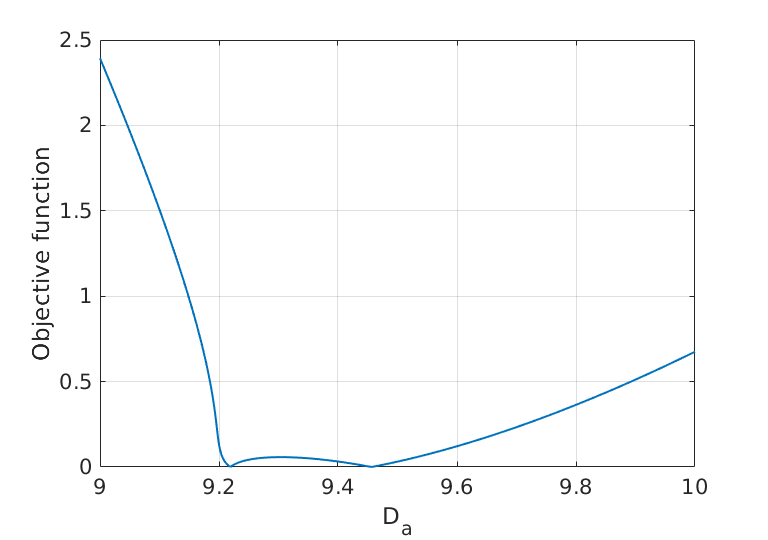

% Plot objective function around hopf for graphical aid
P.PlotObjectiveFunction(Da, 1000, [9 10])

% Change bounds to get another hopf
P.SetUpper(Da, 9.3)


	 Class: Parameter
	 Tag:   D_a
	 Value: 9.3000e+00
	 Lower: 0.0000e+00
	 Upper: 9.3000e+00
	 Fixed: no


%P.SetValue(Da, 7.5)

% Make another search
P.HopfSearch;

 
 Iteration   Func-count     min f(x)         Procedure
     0            1         0.057711         
     1            8         0.057711         initial simplex
     2           10         0.057711         contract outside
     3           12         0.057711         contract inside
     4           14        0.0360019         contract inside
     5           15        0.0360019         reflect
     6           16        0.0360019         reflect
     7           17        0.0360019         reflect
     8           18        0.0360019         reflect
     9           19        0.0360019         reflect
    10           21        0.0202578         expand
    11           23       0.00594452         reflect
    12           24       0.00594452         reflect
    13           26       0.00594452         contract inside
    14           28       0.00594452         contract inside
    15           29       0.00594452         reflect
    16           31       0.00594452         contract 

% New results
P.ShowReport;



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_rev_idx1.m
    Variables ....................................... x1 = 1.145256e-02, x2 = 6.379302e-01, x3 = 1.144289e+01, x4 = 9.885474e-01
    Search Parameters ............................... Da = 9.300000e+00
    Fixed Parameters ................................ g = 3.255732e+01, beta = 3.165177e+00, c = 4.518012e+00, H1 = 9.585506e+00, H2 = 6.527242e+01, Keq = 5.570198e+01

* Model Analysis

    Differential Index .............................. 1
    Explicit Algebraic Eqs .......................... 1
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 3

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ x1 = 1.306627e-02, x2 = 7.278172e-01, x3 = 1.000527e+01, x4 = 9.869337e-01
    par-values ..........................

% Keep new hopf
P.KeepBP;
P.ShowReport



==================== Reports ====================

* Initial Setup

    Model ........................................... cstr_rev_idx1.m
    Variables ....................................... x1 = 1.145256e-02, x2 = 6.379302e-01, x3 = 1.144289e+01, x4 = 9.885474e-01
    Search Parameters ............................... Da = 9.300000e+00
    Fixed Parameters ................................ g = 3.255732e+01, beta = 3.165177e+00, c = 4.518012e+00, H1 = 9.585506e+00, H2 = 6.527242e+01, Keq = 5.570198e+01

* Model Analysis

    Differential Index .............................. 1
    Explicit Algebraic Eqs .......................... 1
    Hidden Algebraic Eqs ............................ 0
    Dynamic Degrees of Freedom ...................... 3

* Active Search

    Hopf found? ..................................... Yes.

    x-values ........................................ x1 = 1.306627e-02, x2 = 7.278172e-01, x3 = 1.000527e+01, x4 = 9.869337e-01
    par-values ..........................

## 7) Continuation

% Steady state continuation
P.SSContinuation(Da, 1000, [9,10])


Runing steady-state continuation...

Iter: 1000	 norm: 5.959116e-15

Finished!

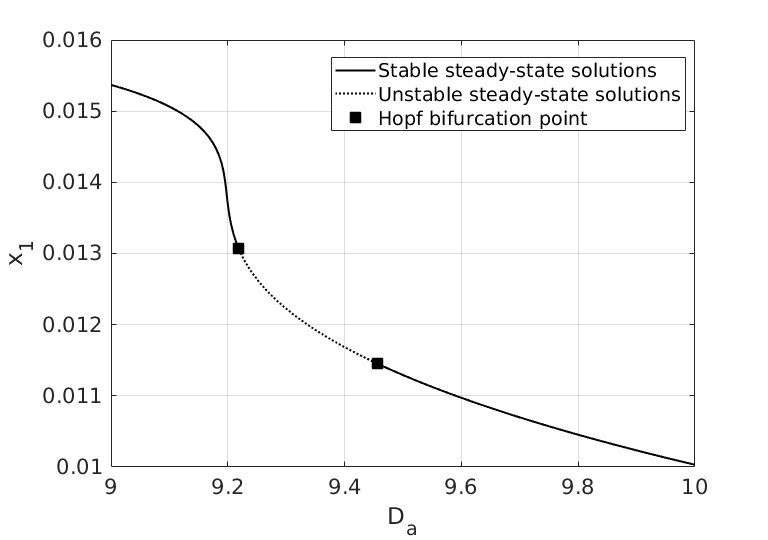

% Plot the branch diagram
P.PlotBranchDiagram(Da, x1)

% Periodic continuation
P.ShiftToBP(2)
P.conopt.ds = 1e-3;
P.conopt.kmax = 490;
P.conopt.algorithm = 'trust-region-reflective';
P.conopt.fixedDs = false;

 P.PeriodicContinuation(Da);

Searching for initial orbit...


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0        322           1e-06                       0.00168
     1        644     2.39283e-11    0.000116524       4.45e-05      
     2        966     1.60283e-18    2.36821e-05       7.77e-06      

Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the selected value
of the function tolerance. However, the last step was ineffective.

<

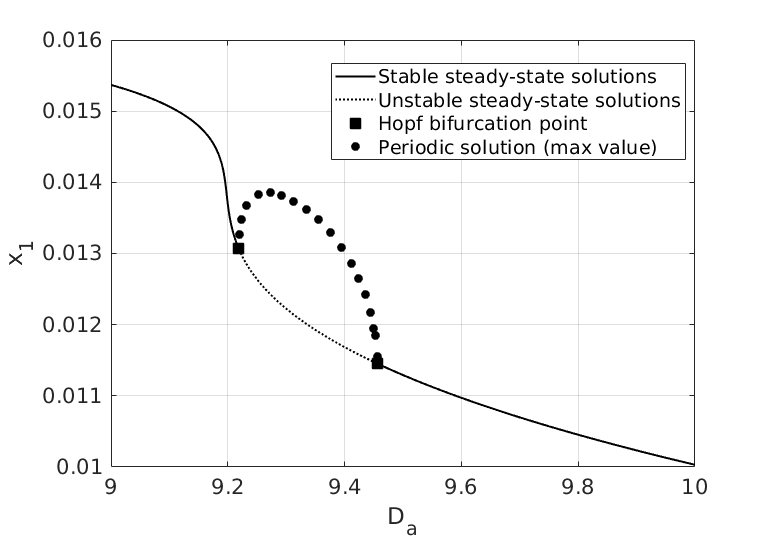

% Plot the branch diagram
P.PlotBranchDiagram(Da, x1)

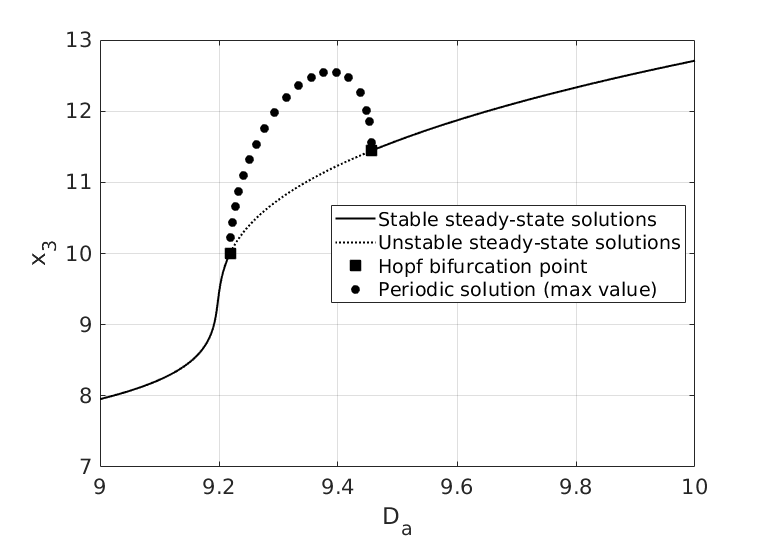

P.PlotBranchDiagram(Da, x3)

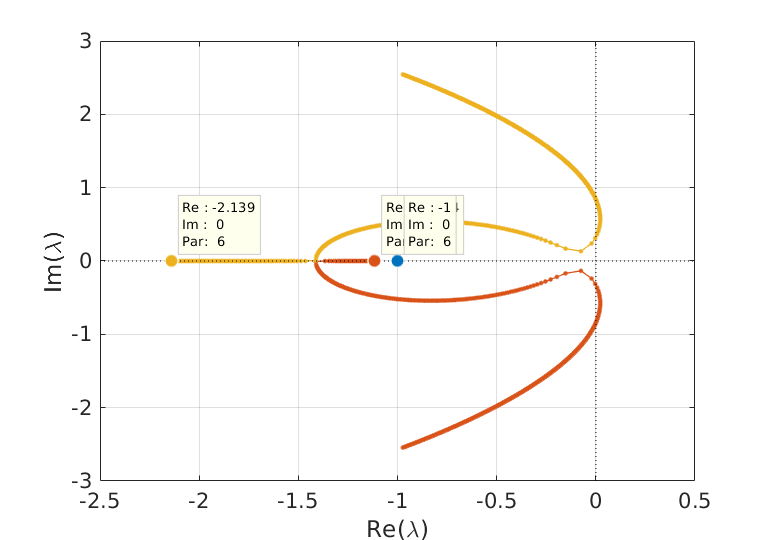

P.PlotEigenMap(Da, 1000, [6 15])

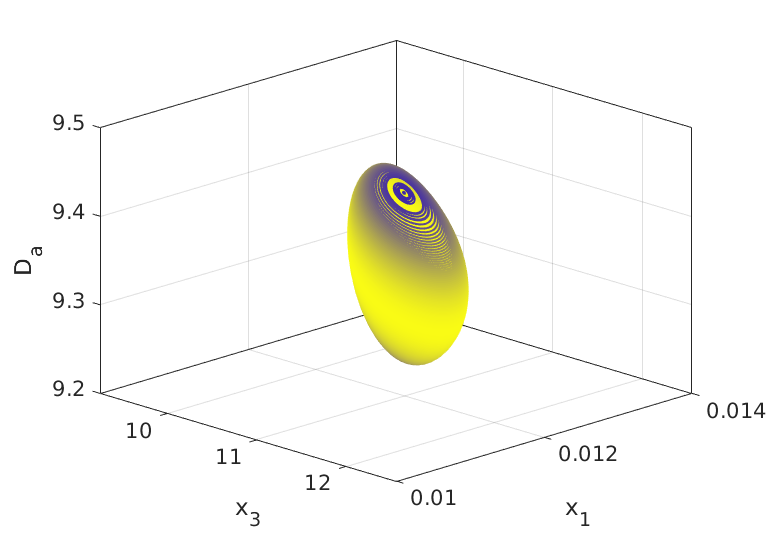

P.PlotOrbitSurface(Da, x3, x1)